# Caracterización y diseño PID del péndulo invertido con hélice

Versión corregida para que todas las respuestas dinámicas provengan de modelo_protyecot.slx. El Live Script identifica parámetros, prepara las entradas, ejecuta Simulink y compara la salida con los experimentos.

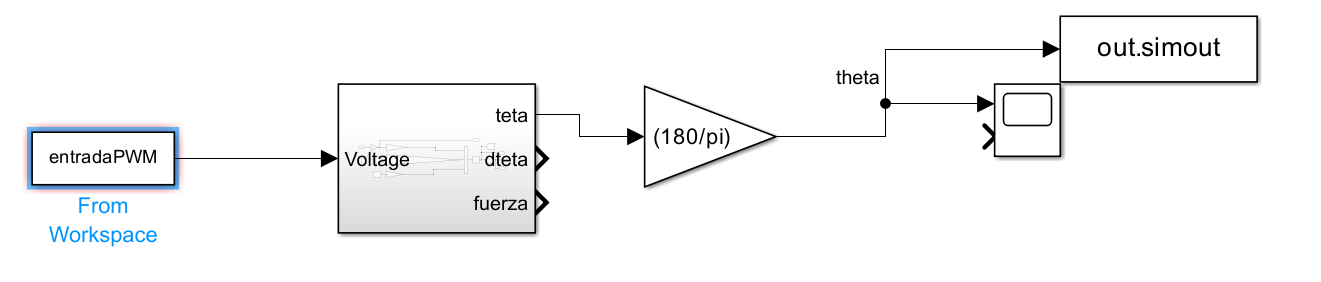

## CORRECCIONES PRINCIPALES

1) La entrada ya no se trata como Constant: se detecta From Workspace y se le entrega la timeseries entradaPWM. 2) Los tres escalones se simulan directamente en Simulink. 3) Se elimina la integración ode45 de la planta dentro del Live Script. 4) La salida no se convierte dos veces a grados, porque el modelo ya contiene el bloque 180/pi. 5) Las condiciones iniciales se asignan a Integrator e Integrator1 en rad/s y rad.

Ejecute las secciones en orden. El bloque To Workspace debe conservar Variable name = simout y Save format = Timeseries; por eso la interfaz de Simulink lo muestra como out.simout.

## 0. OBJETIVO, ARCHIVOS Y CONVENCIONES

Define la finalidad del documento, las unidades y los dos archivos que deben estar junto al Live Script. También aclara que la integración dinámica se ejecuta únicamente con sim().

%% 0. OBJETIVO, ARCHIVOS Y CONVENCIONES
% CARACTERIZACIÓN Y DISEÑO PID DEL PÉNDULO INVERTIDO CON HÉLICE
%
% Este documento tiene dos funciones claramente separadas:
%
%   A) Identificar los parámetros del modelo con los experimentos.
%   B) Ejecutar el modelo matemático EXCLUSIVAMENTE EN SIMULINK y comparar
%      su respuesta con los datos experimentales.
%
% No se integra la ecuación diferencial con ode45 dentro del Live Script.
% Todas las curvas denominadas "Simulink" provienen de la instrucción sim().
%
% Archivos requeridos en la misma carpeta:
%   - Experimentos.xlsx
%   - modelo_protyecot.slx
%
% Estructura que debe tener modelo_protyecot.slx:
%   From Workspace (variable entradaPWM) -> Subsystem -> Gain 180/pi
%   -> To Workspace (variable simout; MATLAB la muestra como out.simout).
%
% Convenciones:
%   theta, dtheta      : rad y rad/s dentro de Simulink.
%   ángulo experimental: grados.
%   entradaPWM         : porcentaje de PWM.
%   simout             : salida en grados, pues el modelo ya incluye 180/pi.

clear; clc; close all; format compact;

% Opciones de trabajo.
abrirModelo = true;              % abre el modelo al preparar la conexión
cerrarModeloAlFinal = false;     % permite inspeccionarlo al terminar
ensayoFriccionMostrar = 3;       % ensayo representativo entre 1 y 10

% Localización robusta de los archivos.
try
    archivoActivo = matlab.desktop.editor.getActiveFilename;
catch
    archivoActivo = '';
end
if isempty(archivoActivo)
    carpetaProyecto = pwd;
else
    carpetaProyecto = fileparts(archivoActivo);
end
addpath(carpetaProyecto);

archivoDatos = fullfile(carpetaProyecto,'Experimentos.xlsx');
modelo = 'modelo_protyecot';
rutaModelo = fullfile(carpetaProyecto,[modelo '.slx']);

assert(isfile(archivoDatos), ...
    'No se encontró Experimentos.xlsx en la carpeta del proyecto.');
assert(isfile(rutaModelo), ...
    'No se encontró modelo_protyecot.slx en la carpeta del proyecto.');


## 1. CARGA Y NORMALIZACIÓN DE LOS EXPERIMENTOS

Carga las oscilaciones libres, el ensayo cuasiestático y los tres historiales de escalón. Corrige las unidades y evita usar las celdas de tiempo dañadas del archivo de fricción.

%% 1. CARGA Y NORMALIZACIÓN DE LOS EXPERIMENTOS
% 1.1 Ensayos de oscilación libre para identificar J y b.
% La columna de tiempo contiene algunas celdas mal interpretadas por Excel;
% por eso se reconstruye con el periodo de muestreo medido.
Ts = 0.01;  % [s]
Mfr = readmatrix(archivoDatos,'Sheet','Experimentos fricción', ...
    'Range','B2:K517');
Mfr = Mfr(~all(isnan(Mfr),2),:);
thetaF_deg = Mfr/1000;                 % miligrados -> grados
Nf = size(thetaF_deg,1);
tF = (0:Nf-1)'*Ts;

% 1.2 Ensayo cuasiestático para gravedad y ganancia de la hélice.
Cest = readcell(archivoDatos,'Sheet','Experimento_ganancia_estatica');
filasEst = 3:12;
pwmEst = aNumero(Cest(filasEst,2));
colsV = [3 6 9 12];
colsAng = [4 7 10 13];
colsTau = [5 8 11 14];
VEst = nan(numel(filasEst),4);
angEst_deg = nan(numel(filasEst),4);
tauEst = nan(numel(filasEst),4);
for r = 1:4
    VEst(:,r) = aNumero(Cest(filasEst,colsV(r)));
    angEst_deg(:,r) = aNumero(Cest(filasEst,colsAng(r)));
    tauEst(:,r) = aNumero(Cest(filasEst,colsTau(r)));
end
% Algunas tensiones quedaron guardadas como 1332 en vez de 1.332 V.
VEst(VEst>20) = VEst(VEst>20)/1000;

% 1.3 Ensayos dinámicos con entrada PWM medida.
hojasEscalon = ["Experimento_escalon_1", ...
                "Experimento_escalon_2", ...
                "Experimento_escalon_3"];
stepData = cell(numel(hojasEscalon),1);
for i = 1:numel(hojasEscalon)
    stepData{i} = leerEscalon(archivoDatos,hojasEscalon(i));
end

fprintf('Datos cargados:\n');

Datos cargados:


fprintf('  Fricción: %d muestras y %d repeticiones.\n', ...
    Nf,size(thetaF_deg,2));

  Fricción: 516 muestras y 10 repeticiones.


fprintf('  Cuasiestático: %d niveles de PWM y 4 repeticiones.\n', ...
    numel(pwmEst));

  Cuasiestático: 10 niveles de PWM y 4 repeticiones.


fprintf('  Escalones: %d ensayos.\n',numel(stepData));

  Escalones: 3 ensayos.


## 2. CARACTERIZACIÓN CUASIESTÁTICA

Identifica el término gravitacional Mgl y la ganancia torque/PWM compatible con el bloque Gain del modelo.

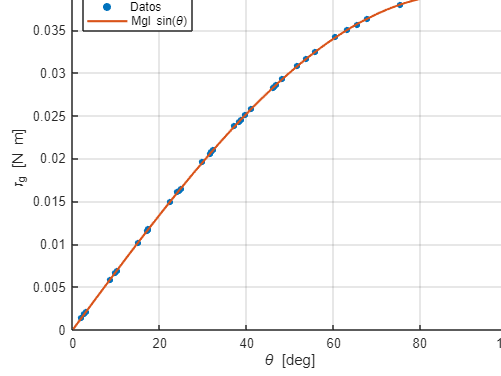

%% 2. CARACTERIZACIÓN CUASIESTÁTICA
% En equilibrio:
%
%   tau_helice = Mgl*sin(theta)
%
% El modelo de Simulink implementa el torque de la hélice como:
%
%   tau_helice = k*L_barra*PWM
%
% Por tanto, primero se identifica Ktau_PWM y luego se calcula
% k = Ktau_PWM/L_barra.

validMgl = isfinite(tauEst) & isfinite(angEst_deg) & ...
    abs(sind(angEst_deg))>0.03;
MglMuestras = tauEst(validMgl)./sind(angEst_deg(validMgl));
Mgl = median(MglMuestras,'omitnan');  % [N*m]

% Apilar las cuatro repeticiones.
pwmRep = repmat(pwmEst,4,1);
VRep = VEst(:);
tauVec = tauEst(:);
valid = isfinite(pwmRep) & isfinite(VRep) & isfinite(tauVec);
pwmRep = pwmRep(valid);
VRep = VRep(valid);
tauVec = tauVec(valid);

% Ajuste lineal que pasa por el origen: es el compatible con el bloque Gain
% del modelo de Simulink, que no contiene offset ni zona muerta.
KtauPWM = (pwmRep'*tauVec)/(pwmRep'*pwmRep);  % [N*m/%PWM]
KtauV = (VRep'*tauVec)/(VRep'*VRep);          % [N*m/V]
tauHatOrigen = KtauPWM*pwmRep;
R2_tau_origen = calcularR2(tauVec,tauHatOrigen);

% Ajuste afín solo para diagnosticar offset/zona muerta del actuador real.
betaPWM = [pwmRep ones(size(pwmRep))]\tauVec;
KtauPWM_afin = betaPWM(1);
tau0PWM = betaPWM(2);
pwmMuertaEquiv = max(0,-tau0PWM/KtauPWM_afin);

% --- GRÁFICA 1: GANANCIA DE HÉLICE ---
figure(1); 
hold on; grid on;
scatter(pwmRep,tauVec,22,'filled','DisplayName','Datos');
uPlot = linspace(0,max(pwmRep)*1.05,250);
plot(uPlot,KtauPWM*uPlot,'LineWidth',1.6, 'DisplayName','Modelo usado en Simulink');
plot(uPlot,KtauPWM_afin*uPlot+tau0PWM,'--','LineWidth',1.2, 'DisplayName','Ajuste afín de diagnóstico');
xlabel('PWM [%]'); ylabel('\tau_h [N m]');
title(sprintf('Ganancia de hélice, R^2 = %.4f',R2_tau_origen));
legend('Location','northwest');

% --- GRÁFICA 2: TÉRMINO GRAVITACIONAL ---
figure(2); 
hold on; grid on;
scatter(angEst_deg(:),tauEst(:),22,'filled','DisplayName','Datos');
aPlot = linspace(0,90,250);
plot(aPlot,Mgl*sind(aPlot),'LineWidth',1.6, 'DisplayName','Mgl sin(\theta)');
xlabel('\theta [deg]'); ylabel('\tau_g [N m]');
title('Término gravitacional');
legend('Location','northwest');

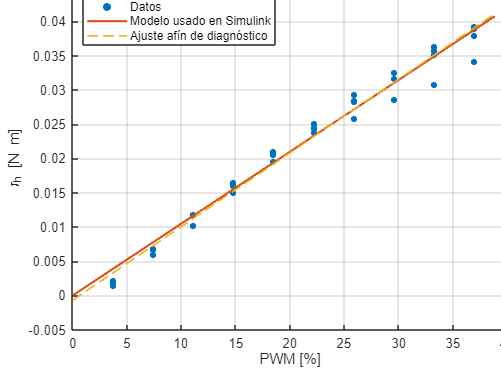


exportgraphics(figure(1), ['D:\Universidad\11vo semestre' ...
    '\Tecnicas de control\Proyecto\Informe_Latex\figuras' ...
    '\Ganancia_estatica.eps'], 'ContentType', 'vector')



fprintf('\nParámetros cuasiestáticos:\n');


Parámetros cuasiestáticos:


fprintf('  Mgl                    = %.6e N*m\n',Mgl);

  Mgl                    = 3.924393e-02 N*m


fprintf('  Ktau_PWM para Simulink = %.6e N*m/%%PWM\n',KtauPWM);

  Ktau_PWM para Simulink = 1.049245e-03 N*m/%PWM


fprintf('  Ktau_V                 = %.6e N*m/V\n',KtauV);

  Ktau_V                 = 1.165828e-02 N*m/V


fprintf('  Zona muerta equivalente (diagnóstico) = %.3f %%PWM\n', ...
    pwmMuertaEquiv);

  Zona muerta equivalente (diagnóstico) = 0.649 %PWM


## 3. IDENTIFICACIÓN DE INERCIA Y FRICCIÓN VISCOSA

Obtiene J y b_p a partir del periodo y la envolvente de las oscilaciones libres. Aquí no se simula la planta.

%% 3. IDENTIFICACIÓN DE INERCIA Y FRICCIÓN VISCOSA
% Cerca del equilibrio theta = 0, la oscilación libre se aproxima por:
%
%   J*theta_dd + b*theta_d + Mgl*theta = 0
%
% Si la envolvente decae como exp(-sigma*t) y el periodo amortiguado es Td:
%
%   omega_d = 2*pi/Td
%   J = Mgl/(sigma^2 + omega_d^2)
%   b = 2*J*sigma
%
% Esta sección SOLO identifica parámetros. La validación dinámica se hace
% después ejecutando modelo_protyecot.slx.

nExpF = size(thetaF_deg,2);
sigma = nan(nExpF,1);
Td = nan(nExpF,1);
Jexp = nan(nExpF,1);
bexp = nan(nExpF,1);
R2_env = nan(nExpF,1);
thetaEqF_deg = nan(nExpF,1);
omega0F_rad_s = nan(nExpF,1);
peaksData = cell(nExpF,1);

for i = 1:nExpF
    y = thetaF_deg(:,i);

    % El valor final se usa como cero local del ensayo. Esto evita que una
    % pequeña cuantización o fricción estática del sensor se confunda con
    % un error del modelo gravitacional.
    nFinal = max(30,round(0.15*numel(y)));
    thetaEqF_deg(i) = median(y(end-nFinal+1:end),'omitnan');
    yc = y-thetaEqF_deg(i);

    % Estimación de velocidad inicial sin derivar muestra a muestra.
    nVel = min(8,numel(tF));
    pVel = polyfit(tF(1:nVel),deg2rad(yc(1:nVel)),1);
    omega0F_rad_s(i) = pVel(1);

    % Envolvente suavizada y máximos de |theta|.
    env = smoothdata(abs(yc),'movmedian',5);
    env = smoothdata(env,'movmean',5);
    [pks,locs] = findpeaks(env, ...
        'MinPeakDistance',round(0.22/Ts));
    keep = pks > max(1,0.04*max(pks));
    pks = pks(keep);
    locs = locs(keep);

    if numel(pks)<5
        warning('Ensayo de fricción %d: hay pocos picos útiles.',i);
        continue
    end

    cEnv = polyfit(tF(locs),log(pks),1);
    sigma(i) = max(0,-cEnv(1));
    R2_env(i) = calcularR2(log(pks),polyval(cEnv,tF(locs)));

    % Periodo entre máximos positivos para no confundir medio periodo.
    [~,locsPos] = findpeaks(yc, ...
        'MinPeakDistance',round(0.45/Ts), ...
        'MinPeakProminence',2);
    if numel(locsPos)>=3
        Td(i) = median(diff(tF(locsPos)),'omitnan');
        omegaD = 2*pi/Td(i);
        Jexp(i) = Mgl/(sigma(i)^2+omegaD^2);
        bexp(i) = 2*Jexp(i)*sigma(i);
    end
    peaksData{i} = [tF(locs) pks];
end

J = median(Jexp,'omitnan');
b_p = median(bexp,'omitnan');
assert(isfinite(J) && J>0,'No fue posible identificar una inercia válida.');
assert(isfinite(b_p) && b_p>=0,'No fue posible identificar una fricción válida.');

tablaIdentificacion = table((1:nExpF)',sigma,Td,Jexp,bexp,R2_env, ...
    thetaEqF_deg,omega0F_rad_s, ...
    'VariableNames',{'Ensayo','sigma_1_s','Td_s','J_kgm2', ...
    'b_Nms_rad','R2_envolvente','theta_eq_deg','omega0_rad_s'});
disp(tablaIdentificacion);

    Ensayo    sigma_1_s    Td_s       J_kgm2      b_Nms_rad     R2_envolvente    theta_eq_deg    omega0_rad_s
    ______    _________    _____    __________    __________    _____________    ____________    ____________
       1       0.86915      0.67    0.00044243    0.00076908       0.98735           0.352          0.12417  
       2       0.93214     0.655    0.00042249    0.00078764       0.96646          -1.056          -2.1277  
       3       0.97134      0.66    0.00042855    0.00083254       0.95611           0.352         -0.64361  
       4       0.95143     0.665    0.00043519     0.0008281       0.94729           0.352          -2.1862  
       5       0.99619      0.66    0.00042832    0.00085338       0

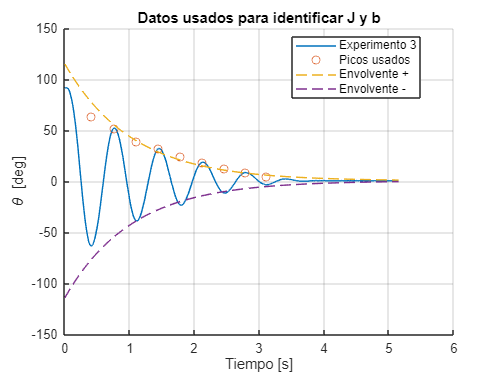


% Mostrar el procedimiento de identificación, sin simular la planta aquí.
i = ensayoFriccionMostrar;
y = thetaF_deg(:,i);
yc = y-thetaEqF_deg(i);
pd = peaksData{i};
figure('Name','Identificación de fricción'); hold on; grid on;
plot(tF,y,'DisplayName',sprintf('Experimento %d',i));
if ~isempty(pd) && isfinite(sigma(i))
    Aenv = exp(mean(log(pd(:,2))+sigma(i)*pd(:,1)));
    plot(pd(:,1),thetaEqF_deg(i)+pd(:,2),'o', ...
        'DisplayName','Picos usados');
    plot(tF,thetaEqF_deg(i)+Aenv*exp(-sigma(i)*tF),'--', ...
        'DisplayName','Envolvente +');
    plot(tF,thetaEqF_deg(i)-Aenv*exp(-sigma(i)*tF),'--', ...
        'DisplayName','Envolvente -');
end
xlabel('Tiempo [s]'); ylabel('\theta [deg]');
title('Datos usados para identificar J y b');
legend('Location','best');


fprintf('\nParámetros dinámicos identificados:\n');


Parámetros dinámicos identificados:


fprintf('  J   = %.6e kg*m^2\n',J);

  J   = 4.285980e-04 kg*m^2


fprintf('  b_p = %.6e N*m*s/rad\n',b_p);

  b_p = 8.303188e-04 N*m*s/rad


## 4. PARÁMETROS QUE RECIBE EL MODELO DE SIMULINK

Convierte los parámetros identificados a las variables exactas que aparecen dentro del subsistema: J, b_p, k, g, masas y longitudes.

%% 4. PARÁMETROS QUE RECIBE EL MODELO DE SIMULINK
% El subsistema mostrado implementa:
%
% theta_dd = (k*L_barra/J)*PWM
%            - g*(m_barra*L_barra/2 + m_helice_motor*L_cm_helice)/J*sin(theta)
%            - (b_p/J)*theta_d
%
% El experimento cuasiestático identifica directamente Mgl. Como el bloque
% de gravedad está escrito con masas y distancias, se define una masa
% equivalente que reproduce exactamente el Mgl identificado.

g = 9.81;
L_barra = 0.195;
m_helice_motor = 0.002;
L_cm_helice = 0.04;

m_barra = 2*(Mgl/g-m_helice_motor*L_cm_helice)/L_barra;
k = KtauPWM/L_barra;  % [N/%PWM]

assert(m_barra>0,'La masa equivalente calculada no es positiva.');

parametrosModelo = table(J,b_p,k,g,m_barra,L_barra, ...
    m_helice_motor,L_cm_helice,Mgl,KtauPWM, ...
    'VariableNames',{'J','b_p','k','g','m_barra','L_barra', ...
    'm_helice_motor','L_cm_helice','Mgl_identificado','Ktau_PWM'});
disp(parametrosModelo);

        J           b_p            k         g      m_barra     L_barra    m_helice_motor    L_cm_helice    Mgl_identificado    Ktau_PWM 
    _________    __________    _________    ____    ________    _______    ______________    ___________    ________________    _________
    0.0004286    0.00083032    0.0053807    9.81    0.040209     0.195         0.002            0.04            0.039244        0.0010492


## 5. CONEXIÓN REAL CON modelo_protyecot.slx

Detecta el bloque From Workspace, los dos integradores y el bloque To Workspace. Esta sección corrige el error causado por buscar un bloque Constant inexistente.

%% 5. CONEXIÓN REAL CON modelo_protyecot.slx
% El código anterior fallaba porque buscaba un bloque llamado Constant y
% trataba de cambiar su parámetro Value. En el modelo mostrado por el usuario
% la entrada es un bloque From Workspace. Por tanto, la conexión correcta es:
%
%   entradaPWM (timeseries) -> From Workspace
%   theta0_sim              -> Integrator1, condición inicial de posición
%   omega0_sim              -> Integrator,  condición inicial de velocidad
%   out.simout              <- To Workspace, salida ya expresada en grados

modeloEstabaCargado = bdIsLoaded(modelo);
if ~modeloEstabaCargado
    load_system(rutaModelo);
end
B = localizarBloquesModelo(modelo);

fprintf('\nConexión detectada:\n');


Conexión detectada:


fprintf('  Entrada temporal : %s\n',B.entrada);

  Entrada temporal : modelo_protyecot/From
Workspace


fprintf('  Planta            : %s\n',B.planta);

  Planta            : modelo_protyecot/Subsystem


fprintf('  Integrador dtheta : %s\n',B.integradorVelocidad);

  Integrador dtheta : modelo_protyecot/Subsystem/Integrator


fprintf('  Integrador theta  : %s\n',B.integradorPosicion);

  Integrador theta  : modelo_protyecot/Subsystem/Integrator1


fprintf('  Salida            : %s -> out.simout\n',B.salida);

  Salida            : modelo_protyecot/To Workspace -> out.simout



if abrirModelo
    open_system(modelo);
end


## 6. VALIDACIÓN DE LOS DIEZ ENSAYOS DE FRICCIÓN EN SIMULINK

Ejecuta diez simulaciones del archivo SLX con entrada PWM igual a cero y compara la salida out.simout con cada medición.

%% 6. VALIDACIÓN DE LOS DIEZ ENSAYOS DE FRICCIÓN EN SIMULINK
% Para cada ensayo se crea una entrada PWM(t)=0 mediante timeseries. Se
% asignan las condiciones iniciales medidas y se ejecuta sim(). El Live
% Script únicamente grafica y calcula el error de la respuesta devuelta por
% Simulink; no resuelve otra copia de la ecuación diferencial.

paramSL = struct('J',J,'b_p',b_p,'k',k,'g',g, ...
    'm_barra',m_barra,'L_barra',L_barra, ...
    'm_helice_motor',m_helice_motor,'L_cm_helice',L_cm_helice);

simFriccion_deg = cell(nExpF,1);
RMSE_F_deg = nan(nExpF,1);
MAE_F_deg = nan(nExpF,1);
R2_F = nan(nExpF,1);
NRMSE_F_pct = nan(nExpF,1);

entradaCero = zeros(size(tF));
for i = 1:nExpF
    yExp = thetaF_deg(:,i);
    yExpRel = yExp-thetaEqF_deg(i);

    [tSL,ySL_rel_deg] = ejecutarModeloSimulink(modelo,B,paramSL, ...
        tF,entradaCero,deg2rad(yExpRel(1)),omega0F_rad_s(i),Ts);

    % La salida del modelo ya está en grados. Se vuelve a sumar el cero local
    % del ensayo únicamente para comparar en las coordenadas del sensor.
    ySL_sensor_deg = ySL_rel_deg+thetaEqF_deg(i);
    yHat = interp1(tSL,ySL_sensor_deg,tF,'linear','extrap');
    simFriccion_deg{i} = yHat;

    M = metricasComparacion(yExp,yHat);
    RMSE_F_deg(i) = M.RMSE_deg;
    MAE_F_deg(i) = M.MAE_deg;
    R2_F(i) = M.R2;
    NRMSE_F_pct(i) = M.NRMSE_pct;
end

tablaValidacionFriccion = table((1:nExpF)',RMSE_F_deg,MAE_F_deg, ...
    NRMSE_F_pct,R2_F, ...
    'VariableNames',{'Ensayo','RMSE_deg','MAE_deg','NRMSE_pct','R2'});
disp(tablaValidacionFriccion);

    Ensayo    RMSE_deg    MAE_deg    NRMSE_pct      R2   
    ______    ________    _______    _________    _______
       1       10.487     6.8167      6.6969      0.81937
       2       7.5628     5.1118      4.8954      0.89422
       3       9.9005     6.6089      6.3941      0.83215
       4        8.649     5.9325      5.6242      0.86276
       5       8.4867     5.7448      5.4686      0.87023
       6       7.7757     5.3089      4.9543       0.8914
       7       10.003     6.6514      6.3735      0.83471
       8       9.0637     5.9723      5.8669      0.85355
       9       8.8567     5.9913      5.6556      0.86108
      10       10.778     7.0599      6.9292      0.80452


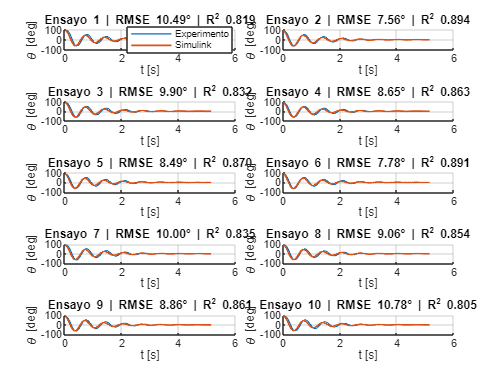


% Comparación visual de las diez repeticiones.
figure('Name','Validación de fricción: experimento vs Simulink');
tiledlayout(5,2,'TileSpacing','compact');
for i = 1:nExpF
    nexttile; hold on; grid on;
    plot(tF,thetaF_deg(:,i),'LineWidth',0.9,'DisplayName','Experimento');
    plot(tF,simFriccion_deg{i},'LineWidth',1.3,'DisplayName','Simulink');
    title(sprintf('Ensayo %d | RMSE %.2f° | R^2 %.3f', ...
        i,RMSE_F_deg(i),R2_F(i)));
    if i==1
        legend('Location','best');
    end
    xlabel('t [s]'); ylabel('\theta [deg]');
end

## 7. VALIDACIÓN DE LOS TRES ENSAYOS DE ESCALÓN EN SIMULINK

Envía cada historial PWM experimental al bloque From Workspace mediante una timeseries y compara la respuesta del modelo con el ángulo medido.

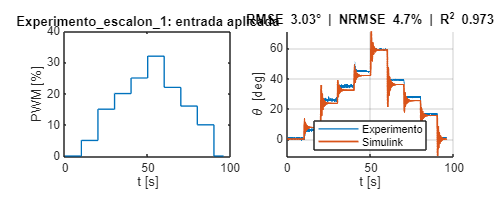

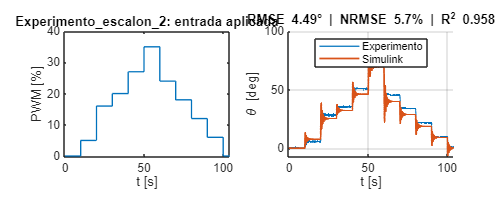

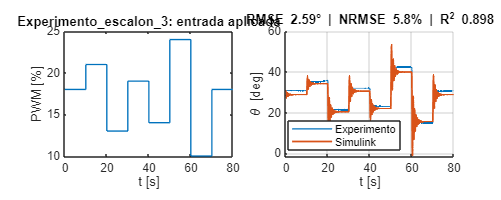

%% 7. VALIDACIÓN DE LOS TRES ENSAYOS DE ESCALÓN EN SIMULINK
% Esta es la corrección principal respecto de la versión anterior: como la
% entrada del modelo es From Workspace, los historiales PWM experimentales
% sí se pueden reproducir directamente. No se usa ode45 en el Live Script.

nStep = numel(stepData);
simEscalon_deg = cell(nStep,1);
RMSE_E_deg = nan(nStep,1);
MAE_E_deg = nan(nStep,1);
R2_E = nan(nStep,1);
NRMSE_E_pct = nan(nStep,1);
omega0_E_rad_s = nan(nStep,1);

% Borra la creación de figura que estaba antes del ciclo, ahora va adentro.

for i = 1:nStep
    D = stepData{i};
    t = D.Tiempo-D.Tiempo(1);
    u = D.PWM;
    yExp = D.Angulo;

    nIni = min(10,numel(t));
    theta0_sim = deg2rad(median(yExp(1:nIni),'omitnan'));
    pVel = polyfit(t(1:nIni),deg2rad(yExp(1:nIni)),1);
    omega0_E_rad_s(i) = pVel(1);

    [tSL,ySL_deg] = ejecutarModeloSimulink(modelo,B,paramSL, ...
        t,u,theta0_sim,omega0_E_rad_s(i),Ts);
    yHat = interp1(tSL,ySL_deg,t,'linear','extrap');
    simEscalon_deg{i} = yHat;

    M = metricasComparacion(yExp,yHat);
    RMSE_E_deg(i) = M.RMSE_deg;
    MAE_E_deg(i) = M.MAE_deg;
    R2_E(i) = M.R2;
    NRMSE_E_pct(i) = M.NRMSE_pct;

    % --- MAGIA PARA FORZAR VENTANAS INDEPENDIENTES ---
    figure('Name', sprintf('Validación de escalones: Ensayo %d', i), ...
           'Position', [100, 100, 1000, 400], ...
           'WindowStyle', 'normal'); % <-- ¡Esto obliga a que se salgan del Live Script!
           
    tiledlayout(1, 2, 'TileSpacing', 'compact');

    nexttile; grid on;
    stairs(t,u,'LineWidth',1.0);
    xlabel('t [s]'); ylabel('PWM [%]');
    title(sprintf('%s: entrada aplicada',hojasEscalon(i)),'Interpreter','none');

    nexttile; hold on; grid on;
    plot(t,yExp,'LineWidth',0.9,'DisplayName','Experimento');
    plot(t,yHat,'LineWidth',1.3,'DisplayName','Simulink');
    xlabel('t [s]'); ylabel('\theta [deg]');
    title(sprintf('RMSE %.2f° | NRMSE %.1f%% | R^2 %.3f', RMSE_E_deg(i),NRMSE_E_pct(i),R2_E(i)));
    legend('Location','best');
end


tablaValidacionEscalones = table(hojasEscalon',RMSE_E_deg,MAE_E_deg, ...
    NRMSE_E_pct,R2_E,omega0_E_rad_s, ...
    'VariableNames',{'Ensayo','RMSE_deg','MAE_deg','NRMSE_pct','R2', 'omega0_rad_s'});
disp(tablaValidacionEscalones);

            Ensayo             RMSE_deg    MAE_deg    NRMSE_pct      R2       omega0_rad_s
    _______________________    ________    _______    _________    _______    ____________
    "Experimento_escalon_1"     3.0273     2.2202      4.7009      0.97288     2.5004e-17 
    "Experimento_escalon_2"     4.4873     3.5406      5.7438      0.95831      -0.026064 
    "Experimento_escalon_3"      2.589     1.8623       5.793      0.89828     1.7175e-15 


## 8. DISEÑO ANALÍTICO DEL PID, SIN SIMULACIÓN EN MATLAB

Calcula las ganancias alrededor de 70 grados. La verificación temporal del PID se reserva para un futuro modelo de lazo cerrado en Simulink.

%% 9. CONSTRUCCIÓN DE LA PLANTA Y DISEÑO PROGRESIVO DEL PID
% 9.1 Construcción de la Planta Linealizada
s = tf('s');
theta_op_deg = 70;
theta_op_rad = deg2rad(theta_op_deg);

Mgl_equiv = Mgl * cos(theta_op_rad); 
a1 = b_p / J;
a2 = Mgl_equiv / J;
num = KtauPWM / J; 

G = minreal((180/pi) * num / (s^2 + a1*s + a2));
disp('--- Planta linealizada usada para diseño (G) ---');

--- Planta linealizada usada para diseño (G) ---


G


G =
 
          140.3
  ---------------------
  s^2 + 1.937 s + 31.32
 
Continuous-time transfer function.
Model Properties


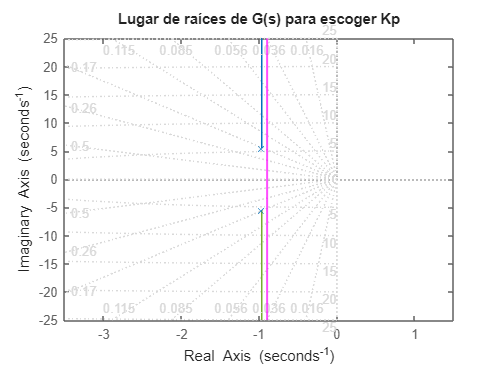


% 9.2 Objetivos de diseño (Líneas guía)
ts = 5;                           % Tiempo de establecimiento deseado [s]
Mp = 0.05;                        % Sobrepico deseado (5 %)
zeta = -log(Mp) / sqrt(pi^2 + log(Mp)^2);
sigma_d = 4.5 / ts;               

% -------------------------------------------------------------------------
% 9.3 Análisis del Controlador Proporcional (P)
Kp = 0.28;   % <--- ESCRIBE TU VALOR DE Kp AQUÍ

figure('Name', 'Paso 1: Lugar de raíces para Kp');
rlocus(G); grid on; sgrid(zeta, []); xline(-sigma_d, 'm', 'LineWidth', 1.5);
title('Lugar de raíces de G(s) para escoger Kp');

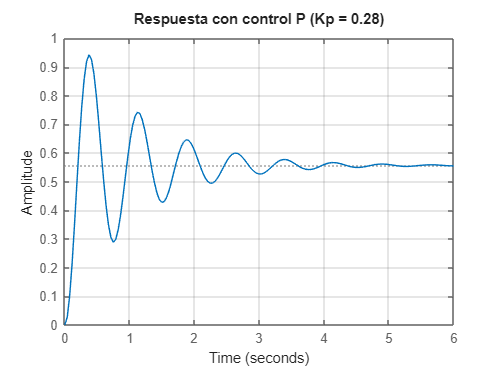


T_P = feedback(Kp*G, 1);
figure('Name', 'Respuesta Lazo Cerrado - Control P');
step(T_P); grid on; title(sprintf('Respuesta con control P (Kp = %.2f)', Kp));

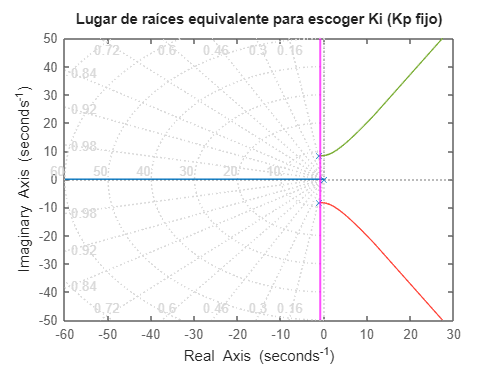


% -------------------------------------------------------------------------
% 9.4 Análisis del Controlador Proporcional-Integral (PI)
Ki = 1.0;    % <--- ESCRIBE TU VALOR DE Ki AQUÍ

L_Ki = minreal(G / (s * (1 + Kp*G)));
figure('Name', 'Paso 2: Lugar de raíces para Ki');
rlocus(L_Ki); grid on; sgrid(zeta, []); xline(-sigma_d, 'm', 'LineWidth', 1.5);
title('Lugar de raíces equivalente para escoger Ki (Kp fijo)');

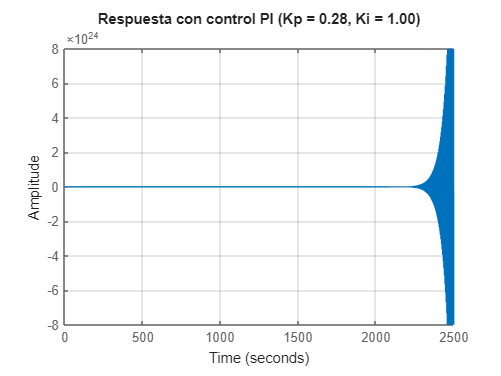


C_PI = Kp + Ki/s;
T_PI = feedback(C_PI*G, 1);
figure('Name', 'Respuesta Lazo Cerrado - Control PI');
step(T_PI);
grid on; 
title(sprintf('Respuesta con control PI (Kp = %.2f, Ki = %.2f)', Kp, Ki));

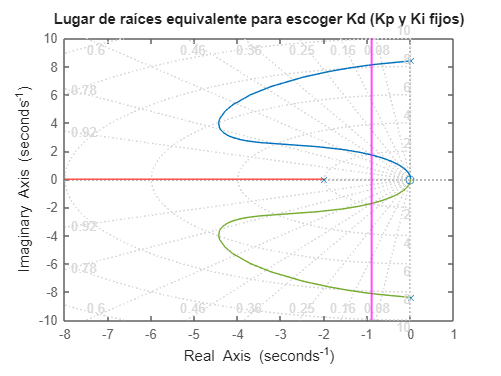


% -------------------------------------------------------------------------
% 9.5 Análisis del Controlador PID completo con Filtro Derivativo
Kd = 0.2;    % <--- ESCRIBE TU VALOR DE Kd AQUÍ

L_Kd = minreal((s*G) / (1 + G*(Kp + Ki/s)));
figure('Name', 'Paso 3: Lugar de raíces para Kd');
rlocus(L_Kd); grid on; sgrid(zeta, []); xline(-sigma_d, 'm', 'LineWidth', 1.5);
title('Lugar de raíces equivalente para escoger Kd (Kp y Ki fijos)');


N_filtro = 100; % Parámetro estándar del filtro de Simulink
C_PID = Kp + Ki/s + Kd*(N_filtro*s)/(s + N_filtro);
T_PID = feedback(C_PID*G, 1);

fprintf('\n--- Controlador PID Final ---\n');


--- Controlador PID Final ---


C_PID


C_PID =
 
  20.28 s^2 + 29 s + 100
  ----------------------
       s^2 + 100 s
 
Continuous-time transfer function.
Model Properties


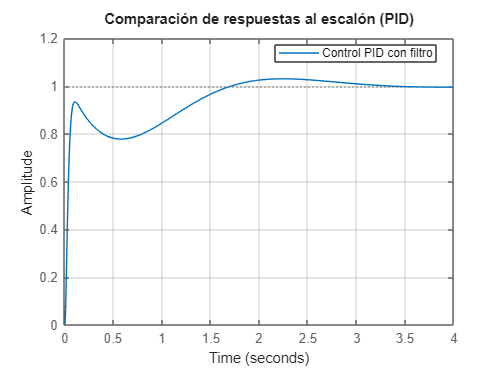


% 9.6 Comparación Final
figure('Name', 'PID');
step(T_PID); grid on;
title('Comparación de respuestas al escalón (PID)');
legend('Control PID con filtro', 'Location', 'best');

## ffff

%% 10. EVALUACIÓN FINAL PARA EL INFORME: MÚLTIPLES ESCENARIOS
disp('Ejecutando simulaciones comparativas para el informe...');

Ejecutando simulaciones comparativas para el informe...


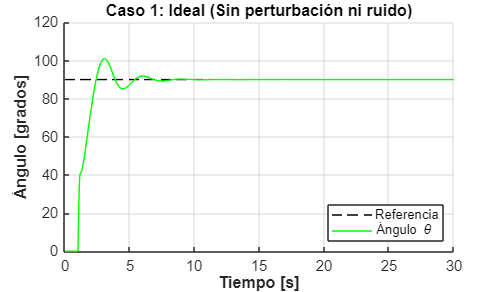

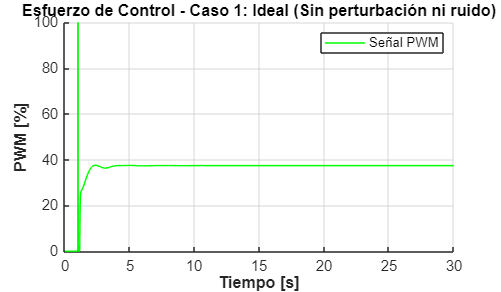

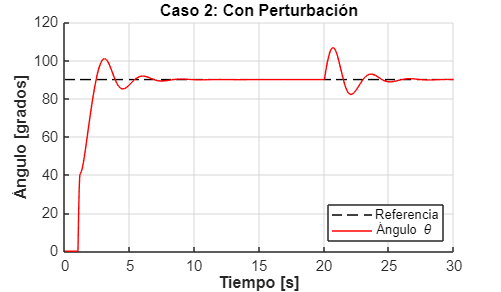

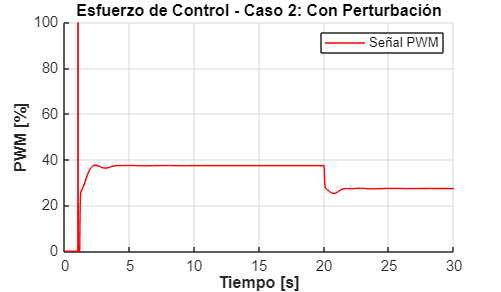

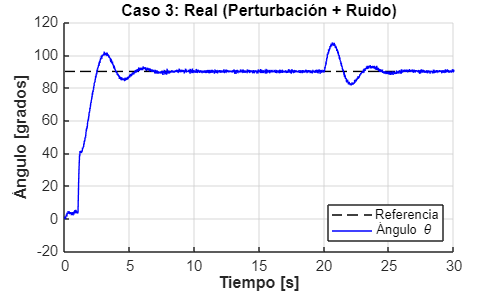

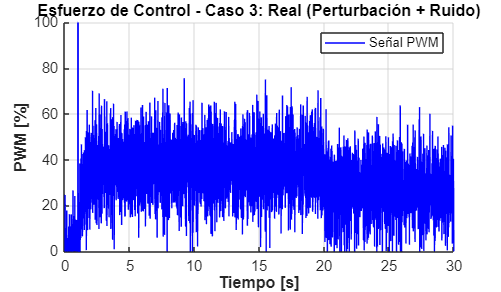

modelo_lc = 'lazo_cerrado';

% =========================================================================
% PARÁMETROS DE SIMULACIÓN (Cámbialos aquí para probar diferentes cosas)
% =========================================================================
tiempo_simulacion = 30;          % Segundos totales a simular
magnitud_perturbacion = 10;      % Tamaño del golpe al PWM (ej. 10, -15, 20)
potencia_ruido_sensor = 0.0025;  % Intensidad del ruido (ej. 0.0025 o 0.0005)
theta_ref = 90;
tiempo_perturbacion = 20; 
% =========================================================================

% Arrays para inyectar en los 3 escenarios
% (Escenario 1: Ideal | Escenario 2: Perturbación | Escenario 3: Real con Ruido)
amps_perturbacion = [0, magnitud_perturbacion, magnitud_perturbacion]; 
pots_ruido        = [0, 0, potencia_ruido_sensor];

resultados_y = cell(3,1);
resultados_u = cell(3,1);
tiempo_sim = cell(3,1);

for i = 1:3
    simIn = Simulink.SimulationInput(modelo_lc);
    
    % Parámetros físicos
    simIn = setVariable(simIn, 'J', J); simIn = setVariable(simIn, 'b_p', b_p);
    simIn = setVariable(simIn, 'k', k); simIn = setVariable(simIn, 'g', g);
    simIn = setVariable(simIn, 'm_barra', m_barra); simIn = setVariable(simIn, 'L_barra', L_barra);
    simIn = setVariable(simIn, 'm_helice_motor', m_helice_motor); 
    simIn = setVariable(simIn, 'L_cm_helice', L_cm_helice);
    
    % Controlador
    simIn = setVariable(simIn, 'Kp', Kp); simIn = setVariable(simIn, 'Ki', Ki);
    simIn = setVariable(simIn, 'Kd', Kd); simIn = setVariable(simIn, 'N', 100);
    
    % Inyectar Perturbación y Ruido del caso actual
    simIn = setVariable(simIn, 'Amp_Perturbacion', amps_perturbacion(i));
     simIn = setVariable(simIn, 'Tiempo_Perturbacion', tiempo_perturbacion);
    simIn = setVariable(simIn, 'Potencia_Ruido', pots_ruido(i));
    
    % Configurar tiempo de simulación y ejecutar
    simIn = setModelParameter(simIn, 'StopTime', num2str(tiempo_simulacion), 'ReturnWorkspaceOutputs', 'on');
    out = sim(simIn);
    
    % --- EXTRACCIÓN INVENCIBLE ---
    t = out.tout;
    
    raw_y = out.get('simout');
    if isa(raw_y, 'timeseries'), y = raw_y.Data;
    elseif isstruct(raw_y) && isfield(raw_y, 'signals'), y = raw_y.signals.values;
    else, y = raw_y; end
    if size(y, 2) > 1, y = y(:, 1); end
    y = y(:);
    
    raw_u = out.get('simout_u');
    if isa(raw_u, 'timeseries'), u = raw_u.Data;
    elseif isstruct(raw_u) && isfield(raw_u, 'signals'), u = raw_u.signals.values;
    else, u = raw_u; end
    if size(u, 2) > 1, u = u(:, 1); end
    u = u(:);
    
    min_len = min([length(t), length(y), length(u)]);
    tiempo_sim{i} = t(1:min_len);
    resultados_y{i} = y(1:min_len);
    resultados_u{i} = u(1:min_len);
end

% -------------------------------------------------------------------------
% GRÁFICAS TOTALMENTE INDIVIDUALES (6 FIGURAS SEPARADAS)
% -------------------------------------------------------------------------
titulos_casos = {'Caso 1: Ideal (Sin perturbación ni ruido)', ...
                 'Caso 2: Con Perturbación', ...
                 'Caso 3: Real (Perturbación + Ruido)'};
             
colores = {'g', 'r', 'b'};
grosores_y = [0.5, 0.5, 0.5];
grosores_u = [0.5, 0.5, 0.5]; 

for i = 1:3
    % 1. Figura de Ángulo
    figure('Name', sprintf('Ángulo - %s', titulos_casos{i}), 'Color', 'w', 'Position', [100+(i*20) 100+(i*20) 600 350]);
    hold on; grid on;
    set(gca, 'GridColor', [0.8 0.8 0.8], 'GridAlpha', 0.5, 'FontSize', 11);
    
    % El xlim y referencian usan el tiempo_simulacion automático
    plot([0 tiempo_simulacion], [theta_ref theta_ref], 'k--', 'LineWidth', 0.5, 'DisplayName', 'Referencia');
    plot(tiempo_sim{i}, resultados_y{i}, colores{i}, 'LineWidth', grosores_y(i), 'DisplayName', 'Ángulo \theta');
    
    title(titulos_casos{i}, 'FontWeight', 'bold');
    ylabel('Ángulo [grados]', 'FontWeight', 'bold');
    xlabel('Tiempo [s]', 'FontWeight', 'bold');
    legend('Location', 'southeast');
    xlim([0 tiempo_simulacion]);

    % 2. Figura de PWM
    figure('Name', sprintf('PWM - %s', titulos_casos{i}), 'Color', 'w', 'Position', [150+(i*20) 150+(i*20) 600 350]);
    hold on; grid on;
    set(gca, 'GridColor', [0.8 0.8 0.8], 'GridAlpha', 0.5, 'FontSize', 11);
    
    plot(tiempo_sim{i}, resultados_u{i}, colores{i}, 'LineWidth', grosores_u(i), 'DisplayName', 'Señal PWM');
    
    title(sprintf('Esfuerzo de Control - %s', titulos_casos{i}), 'FontWeight', 'bold');
    ylabel('PWM [%]', 'FontWeight', 'bold');
    xlabel('Tiempo [s]', 'FontWeight', 'bold');
    legend('Location', 'northeast');
    xlim([0 tiempo_simulacion]);
end


disp('¡Se han generado las 6 gráficas paramétricas! Listo para el informe.');

¡Se han generado las 6 gráficas paramétricas! Listo para el informe.


## 10. CIERRE

Cierra opcionalmente el modelo y deja preparado el guardado de parámetros.

%% 10. CIERRE
if cerrarModeloAlFinal && ~modeloEstabaCargado
    close_system(modelo,0);
end

% Guardado opcional de parámetros y métricas:
% save(fullfile(carpetaProyecto,'parametros_identificados.mat'), ...
%     'J','b_p','k','Mgl','KtauPWM','parametrosModelo','PID', ...
%     'tablaValidacionFriccion','tablaValidacionEscalones');


## FUNCIONES AUXILIARES

Contiene la detección de bloques, la preparación de SimulationInput, la ejecución de sim(), la lectura de simout y las métricas de validación.

%% FUNCIONES AUXILIARES
function B = localizarBloquesModelo(modelo)
% LOCALIZARBLOQUESMODELO encuentra los bloques usados por el código.
% La entrada debe ser From Workspace. Si el archivo cargado todavía tiene
% un Constant, se entrega un error explícito para evitar una simulación
% incorrecta de los ensayos de escalón.

    entrada = find_system(modelo,'SearchDepth',1, ...
        'BlockType','FromWorkspace');
    if isempty(entrada)
        constante = find_system(modelo,'SearchDepth',1, ...
            'BlockType','Constant');
        if ~isempty(constante)
            error(['El modelo cargado todavía contiene el bloque %s. ' ...
                'Reemplácelo por From Workspace y configure la variable ' ...
                'entradaPWM, como en la imagen enviada.'],constante{1});
        end
        error('No se encontró un bloque From Workspace en %s.',modelo);
    end
    B.entrada = entrada{1};

    planta = find_system(modelo,'SearchDepth',1,'BlockType','SubSystem');
    planta = planta(~strcmp(planta,modelo));
    if isempty(planta)
        error('No se encontró el subsistema de la planta.');
    end
    B.planta = planta{1};

    B.integradorVelocidad = [B.planta '/Integrator'];
    B.integradorPosicion = [B.planta '/Integrator1'];
    if getSimulinkBlockHandle(B.integradorVelocidad)==-1 || ...
            getSimulinkBlockHandle(B.integradorPosicion)==-1
        error(['No se encontraron Integrator e Integrator1 dentro de %s. ' ...
            'Integrator debe representar velocidad e Integrator1 posición.'], ...
            B.planta);
    end

    salida = find_system(modelo,'SearchDepth',1,'BlockType','ToWorkspace');
    if isempty(salida)
        error('No se encontró el bloque To Workspace del ángulo.');
    end
    B.salida = salida{1};
end


function [tSim,ySim_deg] = ejecutarModeloSimulink( ...
    modelo,B,p,tEntrada,uEntrada,theta0,omega0,pasoMax)
% EJECUTARMODELOSIMULINK ejecuta exclusivamente el archivo SLX.
%
% tEntrada, uEntrada : señal experimental enviada a From Workspace.
% theta0, omega0     : condiciones iniciales en rad y rad/s.
% ySim_deg           : salida del modelo; ya está en grados por el Gain 180/pi.

    tEntrada = tEntrada(:)-tEntrada(1);
    uEntrada = uEntrada(:);
    [tEntrada,idx] = unique(tEntrada,'stable');
    uEntrada = uEntrada(idx);

    assert(numel(tEntrada)==numel(uEntrada), ...
        'Tiempo y PWM deben tener igual número de muestras.');
    assert(all(diff(tEntrada)>0), ...
        'El tiempo enviado a From Workspace debe ser estrictamente creciente.');

    entradaPWM = timeseries(uEntrada,tEntrada);
    entradaPWM = setinterpmethod(entradaPWM,'zoh');

    simIn = Simulink.SimulationInput(modelo);

    % Variables usadas por los bloques Gain del subsistema.
    simIn = setVariable(simIn,'J',p.J);
    simIn = setVariable(simIn,'b_p',p.b_p);
    simIn = setVariable(simIn,'k',p.k);
    simIn = setVariable(simIn,'g',p.g);
    simIn = setVariable(simIn,'m_barra',p.m_barra);
    simIn = setVariable(simIn,'L_barra',p.L_barra);
    simIn = setVariable(simIn,'m_helice_motor',p.m_helice_motor);
    simIn = setVariable(simIn,'L_cm_helice',p.L_cm_helice);

    % Señal temporal y condiciones iniciales.
    simIn = setVariable(simIn,'entradaPWM',entradaPWM);
    simIn = setVariable(simIn,'theta0_sim',theta0);
    simIn = setVariable(simIn,'omega0_sim',omega0);

    simIn = setBlockParameter(simIn,B.entrada, ...
        'VariableName','entradaPWM');
    simIn = setBlockParameter(simIn,B.integradorVelocidad, ...
        'InitialCondition','omega0_sim');
    simIn = setBlockParameter(simIn,B.integradorPosicion, ...
        'InitialCondition','theta0_sim');
    % Compatibilidad entre versiones de MATLAB/Simulink:
    % setBlockParameter admite un solo par parámetro-valor por llamada en
    % algunas versiones. Por eso se configuran por separado.
    simIn = setBlockParameter(simIn,B.salida, ...
        'VariableName','simout');
    simIn = setBlockParameter(simIn,B.salida, ...
        'SaveFormat','Timeseries');

    % El solver se ejecuta dentro de Simulink, no en el Live Script.
    simIn = setModelParameter(simIn, ...
        'StartTime','0', ...
        'StopTime',num2str(tEntrada(end),'%.12g'), ...
        'SolverType','Variable-step', ...
        'Solver','ode45', ...
        'MaxStep',num2str(pasoMax,'%.12g'), ...
        'ReturnWorkspaceOutputs','on');

    simOut = sim(simIn);
    salida = simOut.get('simout');
    [tSim,ySim_deg] = leerSalidaSimulink(salida);
end


function [t,y] = leerSalidaSimulink(salida)
% Admite los formatos comunes del bloque To Workspace.
    if isa(salida,'timeseries')
        t = salida.Time(:);
        y = squeeze(salida.Data);
        y = y(:);
    elseif isstruct(salida) && isfield(salida,'time') && ...
            isfield(salida,'signals')
        t = salida.time(:);
        y = squeeze(salida.signals.values);
        y = y(:);
    elseif isnumeric(salida) && size(salida,2)>=2
        t = salida(:,1);
        y = salida(:,2);
    else
        error(['Formato de simout no reconocido. Configure To Workspace ' ...
            'con Save format = Timeseries.']);
    end

    valid = isfinite(t) & isfinite(y);
    t = t(valid);
    y = y(valid);
    [t,idx] = unique(t,'stable');
    y = y(idx);
end


function M = metricasComparacion(y,yhat)
    y = y(:);
    yhat = yhat(:);
    valid = isfinite(y) & isfinite(yhat);
    y = y(valid);
    yhat = yhat(valid);
    e = yhat-y;

    M.RMSE_deg = sqrt(mean(e.^2));
    M.MAE_deg = mean(abs(e));
    rango = max(y)-min(y);
    if rango>eps
        M.NRMSE_pct = 100*M.RMSE_deg/rango;
    else
        M.NRMSE_pct = NaN;
    end
    M.R2 = calcularR2(y,yhat);
end


function x = aNumero(C)
% Convierte celdas con coma o punto decimal a double.
    x = nan(size(C));
    for k = 1:numel(C)
        v = C{k};
        if isnumeric(v) && isscalar(v)
            x(k) = double(v);
        elseif islogical(v) && isscalar(v)
            x(k) = double(v);
        elseif ischar(v) || (isstring(v) && isscalar(v))
            x(k) = str2double(strrep(strtrim(string(v)),',','.'));
        end
    end
end


function D = leerEscalon(archivo,hoja)
% Lee un ensayo y garantiza tiempo creciente desde cero.
    M = readmatrix(archivo,'Sheet',hoja);
    M = M(all(isfinite(M(:,1:3)),2),1:3);
    [t,idx] = unique(M(:,1),'stable');
    pwm = M(idx,2);
    ang = M(idx,3);
    [t,orden] = sort(t);
    pwm = pwm(orden);
    ang = ang(orden);
    D = table(t,pwm,ang, ...
        'VariableNames',{'Tiempo','PWM','Angulo'});
end


function R2 = calcularR2(y,yhat)
    y = y(:);
    yhat = yhat(:);
    valid = isfinite(y) & isfinite(yhat);
    y = y(valid);
    yhat = yhat(valid);
    den = sum((y-mean(y)).^2);
    if den<=eps
        R2 = NaN;
    else
        R2 = 1-sum((y-yhat).^2)/den;
    end
end

Imagenes Vectoriales

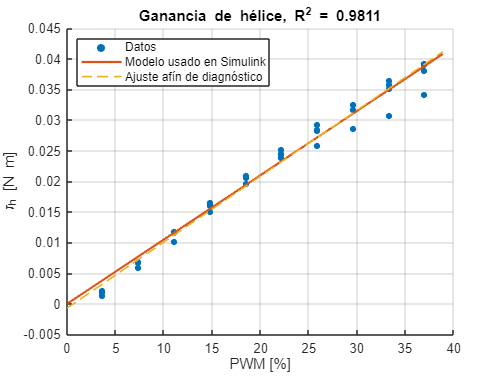

exportgraphics(figure(1), ['D:\Universidad\11vo semestre' ...
    '\Tecnicas de control\Proyecto\Informe_Latex\figuras' ...
    '\Ganancia_estatica.eps'], 'ContentType', 'vector')


exportgraphics(figure(3) , ['D:\Universidad\11vo semestre\' ...
    'Tecnicas de control\Proyecto\Informe_Latex\figuras\' ...
    'Oscilacion_libre.eps'], 'ContentType', 'vector')


exportgraphics(figure(5) , ['D:\Universidad\11vo semestre\' ...
    'Tecnicas de control\Proyecto\Informe_Latex\figuras\' ...
    'Experimento_escalones_1.eps'], 'ContentType', 'vector')


exportgraphics(figure(6) , ['D:\Universidad\11vo semestre\' ...
    'Tecnicas de control\Proyecto\Informe_Latex\figuras\' ...
    'Experimento_escalones_2.eps'], 'ContentType', 'vector')


exportgraphics(figure(7) , ['D:\Universidad\11vo semestre\' ...
    'Tecnicas de control\Proyecto\Informe_Latex\figuras\' ...
    'Experimento_escalones_3.eps'], 'ContentType', 'vector')


exportgraphics(figure(12) , ['D:\Universidad\11vo semestre\' ...
    'Tecnicas de control\Proyecto\Informe_Latex\figuras\' ...
    'RootLocus_PI.eps'], 'ContentType', 'vector')


exportgraphics(figure(13) , ['D:\Universidad\11vo semestre\' ...
    'Tecnicas de control\Proyecto\Informe_Latex\figuras\' ...
    'Step_PID.eps'], 'ContentType', 'vector')

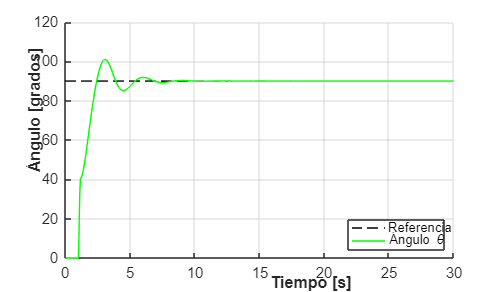


exportgraphics(figure(14) , ['D:\Universidad\11vo semestre\' ...
    'Tecnicas de control\Proyecto\Informe_Latex\figuras\' ...
    'Respuesta_90°_Caso_1.eps'], 'ContentType', 'vector')

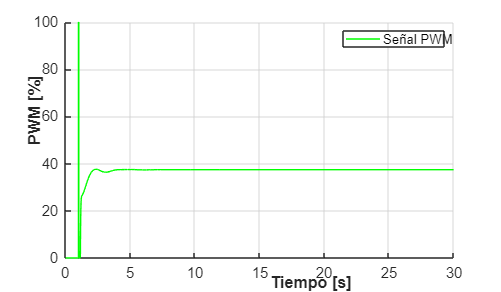


exportgraphics(figure(15) , ['D:\Universidad\11vo semestre\' ...
    'Tecnicas de control\Proyecto\Informe_Latex\figuras\' ...
    'esfuerzo_control_90°_Caso_1.eps'], 'ContentType', 'vector')

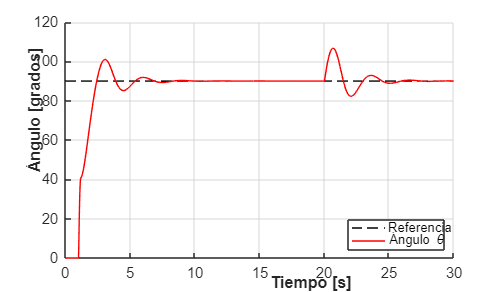


exportgraphics(figure(16) , ['D:\Universidad\11vo semestre\' ...
    'Tecnicas de control\Proyecto\Informe_Latex\figuras\' ...
    'Respuesta_90°_Caso_2.eps'], 'ContentType', 'vector')

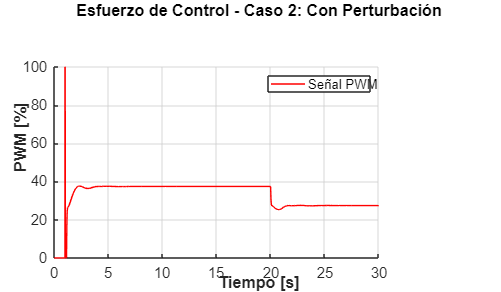


exportgraphics(figure(17) , ['D:\Universidad\11vo semestre\' ...
    'Tecnicas de control\Proyecto\Informe_Latex\figuras\' ...
    'esfuerzo_control_90°_Caso_2.eps'], 'ContentType', 'vector')

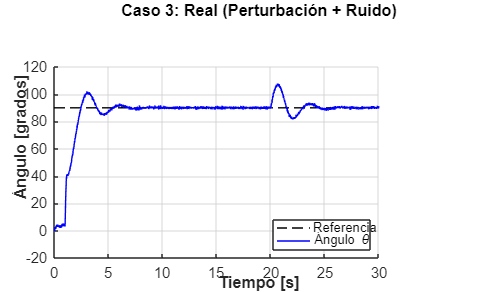


exportgraphics(figure(18) , ['D:\Universidad\11vo semestre\' ...
    'Tecnicas de control\Proyecto\Informe_Latex\figuras\' ...
    'Respuesta_90°_Caso_3.eps'], 'ContentType', 'vector')

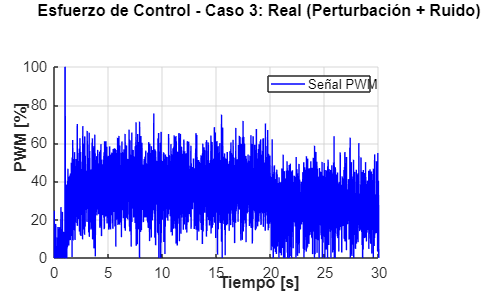


exportgraphics(figure(19) , ['D:\Universidad\11vo semestre\' ...
    'Tecnicas de control\Proyecto\Informe_Latex\figuras\' ...
    'esfuerzo_control_90°_Caso_3.eps'], 'ContentType', 'vector')